# **Encoding**

clc;
clear;
close all;

#### Load Data

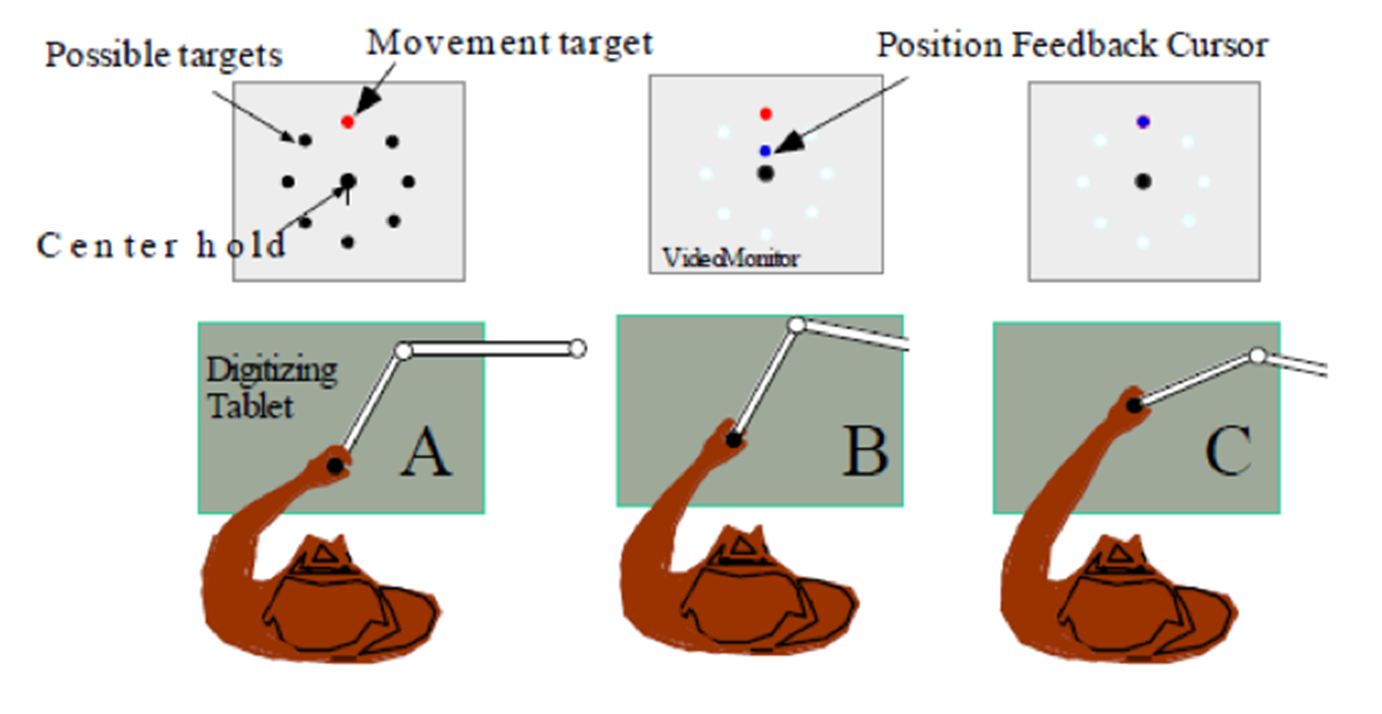

load('data_Flint_2012_e1.mat');
data

data = 다음 필드를 포함한 175×1 struct 배열:
    HandPos
    HandVel
    HandAcc
    Time
    Neuron
    class
    cueOnset
    movementOnset
    movementMax
    movementOffset


#### **Data Setting**

% hand position
hand_pos    = {data.HandPos}';

% direction
dir_list    = 0:45:315;
idx_dir     = [data.class]';
hand_dir    = dir_list(idx_dir);

% trial time
trial_time  = {data.Time}; % the behaior data is recorded every 0.01ms
move_onset  = [data.movementOnset];
move_off    = [data.movementOffset];

#### **Data Processing**

n_trial = length(hand_pos)

n_trial = 175

n_neuron = length(data(1).Neuron)

n_neuron = 196

% Generate Trial x Neuron spike_train_matrix
spike_data = cell(n_trial,n_neuron); 
for i = 1:n_trial
    for j = 1:n_neuron
        spike_data{i,j} = data(i).Neuron(j).Spike;
    end
end

spike_data

spike_data = 175×196 cell 배열
    {80×1 single}    {29×1 single}    {122×1 single}    {44×1 single}    {331×1 single}    {4×1 single}    {79×1 single}    {4×1 single}    {4×1 single}    {7×1 single}    {35×1 single}    {[ 13.1345]}    {15×1 single}    {0×0 single}    {47×1 single}    {58×1 single}    {50×1 single}    {0×1 single}    {105×1 single}    {0×1 single}    {162×1 single}    {145×1 single}    {124×1 single}    {66×1 single}    {0×0 single}    { 97×1 single}    {34×1 single}    {4×1 single}    {0×1 single}    {216×1 single}    {164×1 single}    {3×1 single}    {8×1 single}    { 4×1 single}    {29×1 single}    {165×1 single}    {243×1 single}    {[ 16.6464]}    {42×1 single}    { 5×1 single}    {0×0 single}    {0×1 single}    {29×1 single}    {184×1 single}    {363×1 single}    {162×1 single}    {20×1 single}    {29×1 single}    {0×1 single}    {0×1 single}    {14×1 single}    {11×1 single}    {28×1 single}    {[ 16.6040]}    {122×1 single}    {115×1 single}    {2×1 single}    {1

**Draw Hand Trajectory**

color_set = ["#0072BD" "#D95319" "#EDB120" "#7E2F8E" ...
   "#77AC30" "#4DBEEE" "#A2142F" "#FF00FF"];

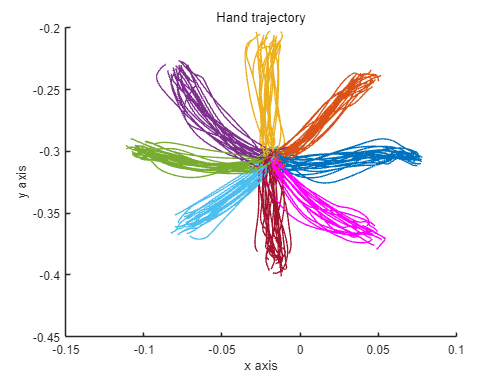

figure
for i = 1:n_trial
    % Set the range of movement using variable "move_onset" and "move_off"
    t_move_idx = move_onset(i):move_off(i);
    hold on
    % Plot the variable "hand_pos", and use the same color for same direction.
    plot(hand_pos{i}(t_move_idx,1),hand_pos{i}(t_move_idx,2),'Color', color_set(idx_dir(i)))
    xlabel('x axis')
    ylabel('y axis')
end
title('Hand trajectory')
hold off

#### **Draw Tuning Curve and Caluculate Preferred Direction (PD)**

By examining the **tuning curve**, we can observe how sensitively a neuron responds to a particular stimulus. 

The direction in which a neuron exhibits the highest firing rate is referred to as the **preferred direction (pd)**.

% Select neuron (example)
idx_neuron = 12;

% Neural firing rate during reaching (move_onset ~ move_offset)
firing_rate = zeros(n_trial,1);

for trial = 1:n_trial
    t_onset = trial_time{trial}(move_onset(trial));
    t_off = trial_time{trial}(move_off(trial));
    firing_rate(trial) = sum(spike_data{trial,idx_neuron} > t_onset & spike_data{trial,idx_neuron} < t_off)/(t_off - t_onset);
end

mean_fr = [];
for dir = 1:length(dir_list)
    mean_fr = [mean_fr mean(firing_rate(hand_dir == dir_list(dir)))];
end

**Encoding Model for Hand Direction**

(**Zt:** firing rate at time t, **θ:** preferred direction of the neuron, 

**b0:** intercept or baseline firing rate,** b1:** weight for the cosine component of θ, **b2: **weight for the sine component of θ, 

**et: **random error)

Let, **Y** as firing rate, **x** as hand direction (angle), **θ** as preferred direction, and **b** as intercept.

Then, the encoding model is, 

Y = cos(x) * cos(θ) + sin(x) * sin(θ) + b 

   = [cos(x) sin(x) 1] * **[cos(θ) sin(θ) b]'**

If we get **B = [cos(θ) sin(θ) b]**, we can easily get θ.

Y = firing_rate;

% Using fitlm function
X = [cos(deg2rad(hand_dir))' sin(deg2rad(hand_dir))'];

model = fitlm(X,Y);

**Y = b + cos(**θ**)*cos(x) + sin(**θ**)*sin(x)**

**Y = B(1) + B(2)*cos(x) + B(3)*sin(x) **

**B(1):** baseline firing rate, **B(2):** Weight for the cosine component (x direction),** B(3):** Weight for the sine component (y direction)

R2 = model.Rsquared.Ordinary;
P = model.Coefficients.pValue;
B = model.Coefficients.Estimate;

% Calculate preferred direction (θ)
p_dir = rad2deg(atan(B(3)/B(2)));

if B(2) >= 0
    if p_dir < 0
        p_dir = 360 + p_dir;
    end
elseif B(2) < 0
    p_dir = 180 + p_dir;
end

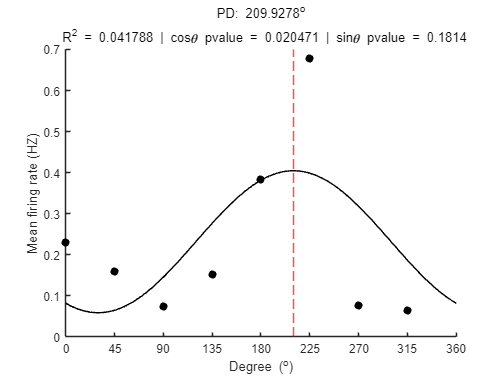

% Draw cosine graph using calculated preferred direction
x_range = [0:0.1:2*pi 2*pi];
y = B(1) + B(2)*cos(x_range) + B(3)*sin(x_range);

figure
hold on
plot(x_range,y,'k','LineWidth',1.2)
plot(deg2rad(dir_list),mean_fr,'k.','MarkerSize',20)
xline(deg2rad(p_dir),'r--')
xlim([0 2*pi])
xticks(0:pi/4:2*pi)
xticklabels(0:45:360)
xlabel('Degree (^o)')
ylabel('Mean firing rate (HZ)')
title(['PD: ' num2str(p_dir) '^o'],[' R^{2} = ' num2str(R2) ' | cos{\theta} pvalue = ' num2str(P(2)) ' | sin{\theta} pvalue = ' num2str(P(3))])

#### **p-value of each coefficient for each neuron**

for i = 1:n_neuron

    % Neural firing rate during reaching (move_onset ~ move_offset)
    n_trial = length(move_onset);
    firing_rate = zeros(n_trial,1);

    for trial = 1:n_trial
        t_onset = trial_time{trial}(move_onset(trial));
        t_off = trial_time{trial}(move_off(trial));
        firing_rate(trial) = sum(spike_data{trial,i} > t_onset & spike_data{trial,i} < t_off)/(t_off - t_onset);
    end

    % Encoding model for hand direction
    Y = firing_rate;

    % Using fitlm function
    X = [cos(deg2rad(hand_dir))' sin(deg2rad(hand_dir))'];
    model = fitlm(X,Y);
    R2(i) = model.Rsquared.Ordinary;
    P(:,i) = model.Coefficients.pValue;

end

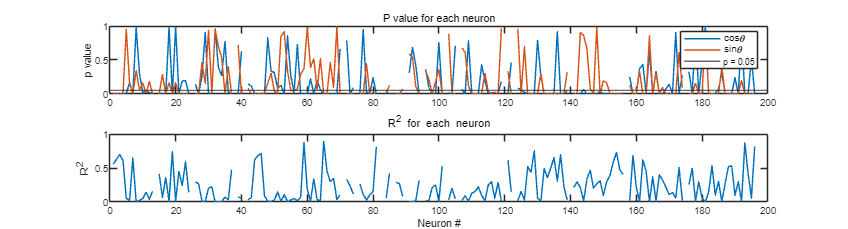

figure('Position',[560 200 2000 540])
subplot(2,1,1)
plot(1:n_neuron, P(2:3,:), 'LineWidth',1.2)
yline(0.05,'LineWidth',1.2)
legend('cos{\theta}','sin{\theta}','p = 0.05')
ylabel('p value')
title('P value for each neuron')
subplot(2,1,2)
plot(1:n_neuron, R2, 'LineWidth',1.2)
xlabel('Neuron #')
ylabel('R^{2}')
title('R^{2} for each neuron')

**Draw Rose Plot**

A** rose plot** is a tool that visualizes the distribution of directional data in the form of a circular histogram. It helps to identify how concentrated the data is in specific directions, allowing for an easy assessment of directionality.

n_trial = length(move_onset);
n_neuron = length(data(1).Neuron);

FR = zeros(n_trial,n_neuron);
for neuron = 1:n_neuron
    for trial = 1:n_trial
        t_onset = trial_time{trial}(move_onset(trial));
        t_off = trial_time{trial}(move_off(trial));
        FR(trial,neuron) = sum(spike_data{trial,neuron} > t_onset & spike_data{trial,neuron} < t_off)/(t_off - t_onset);
    end
end

 **Encoding model for hand direction using matrix form**

Use least squares solution to calculate the coefficients B

% Encoding model for hand direction (same as earlier with matrix form)
Y = FR;
X = [cos(deg2rad(hand_dir))' sin(deg2rad(hand_dir))' ones(n_trial,1)];
B = inv(X'*X)*X'*Y; 

% Calculate preferred direction
PD = zeros(n_neuron,1);

for neuron = 1:n_neuron
    % Calculate preferred direction
    PD(neuron) = rad2deg(atan(B(2,neuron)/B(1,neuron)));

    if B(1,neuron) >= 0
        if PD(neuron) < 0
            PD(neuron) = 360 + PD(neuron);
        end
    elseif B(1,neuron) < 0
        PD(neuron) = 180 + PD(neuron);
    end
    
end

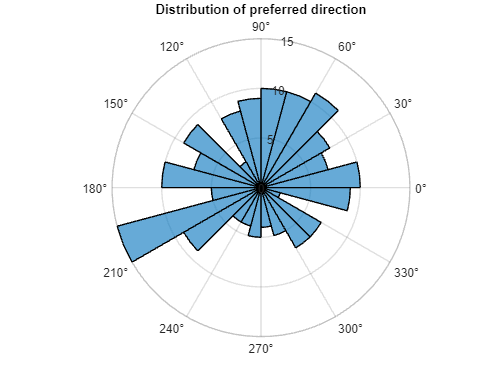

% rose plot
figure
polarhistogram(PD,24)
title('Distribution of preferred direction','FontWeight','Bold')